================================================================================

# First Partial Redemption (3 extra)

## **Ejercicio. Ajuste por mínimos cuadrados (hasta + 3 puntos)**

*(En este ejercicio vamos a hacer los ajustes por mínimos cuadrados a partir de la resolución de sistemas lineales sobredeterminados, tal y como vimos en clase y en la sesión práctica. NO da ningún punto usar para el ajuste herramientas tales como el curve fitter de MATLAB ni la función fit() ni similares.)*

Tenemos los siguientes datos experimentales:


$$
\begin{array}{lcccccc}
x & 0.5 & 2.5 & 6 & 10 & 15 & 20  \\
y & 2.15 & 2.31 & 2.42 & 2.98 &  4.15 &  5.81 \\
\end{array}$$


Queremos realizar un ajuste por mínimos cuadrados a distintas funciones para encontrar el mejor modelo $y = f(x)$.

clear all
xdata = [0.5 2.5 6 10 15 20]';
ydata = [2.15 2.31 2.42 2.98 4.15 5.81]';

#### A) Ajuste a función exponencial $(f_1(x) = a\cdot e^{b\cdot x})$

- **(i)** [1 punto] Obtener la función exponencial $f_1(x) = a\cdot e^{b\cdot x}$ que minimiza el error cuadrático de los datos experimentales dados resolviendo un sistema lineal sobredeterminado. Dar los valores de $a$ y $b$. Guardar la función exponencial resultante del ajuste por mínimos cuadrados como una función anónima $\texttt{f1}$ y escribirla usando el comando $\texttt{fprintf()}$ con 4 decimales en los coeficientes.

- El error SSE (sum of squared errors  - suma de errores al cuadrado) del ajuste a una función exponencial, como la hemos linealizado, no lo podemos tomar del error de la linealización. El error $\texttt{SSE1}$ podemos calcularlo como $(||\mathbf{y} - f_1(\mathbf{x}) ||_2)^2$ para los vectores de datos experimentales $\mathbf{x}$ e $\mathbf{y}$. Calcular este valor de $\texttt{SSE1}$.

- *(En este apartado sí se pueden utilizar funciones de MATLAB para la resolución de sistemas de ecuaciones lineales.)*

% y = a * exp(b * x)
% ln(y) = ln(a) + b*x
% log(y) = b*x + log(a)     // Tendremos que calcular c = log(a) al final

ydata_log = log(ydata);

%      b*x     log(a)
A = [0.5 1; 2.5 1; 6 1; 10 1; 15 1; 20 1];

AtA = A'*A;
Atb = A'*ydata_log;
AtA_Atb = [AtA Atb];

rank(AtA_Atb) == rank(A)    %Sist. compatible determinado

ans = logical
   1


% Resolvemos el sistema para calcular b y log(a)
sols = inv(AtA) * Atb;

b = sols(1);

% sols(2) = log(a)
% e^sols(2) = a
a = exp(sols(2));

residuo = ydata_log - A*sols;
norm2 = norm(residuo,2)

norm2 = 0.1664

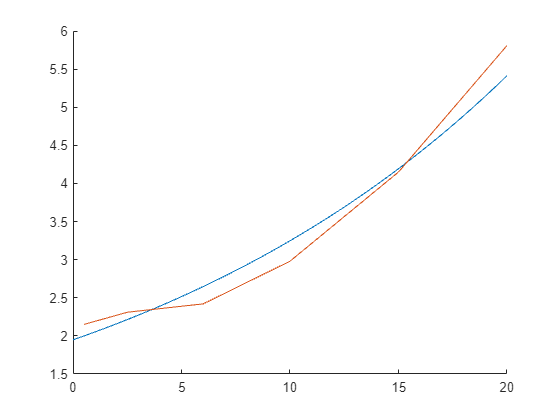

% Guardamos como funcion anonima, el resultado parece bastante parejo
f1 = @(x) a * exp(b*x);
hold on
fplot(f1, [0 20])
plot(xdata, ydata)
hold off

fprintf('y = %1f*e^(%1f*x)', a, b)

y = 1.948196*e^(0.051105*x)

% ERROR SSE1
calcs = a*exp(b*xdata);     % Valores calculados con a y b obtenidas
sse1 = norm(abs(ydata - calcs),2)^2

sse1 = 0.3141

#### B) Ajuste a función logarítmica $(f_2(x) = a\log (x) + b)$

- **(ii)** [1 punto] Obtener la función logarítmica $f_2(x) = a\log (x) + b$ que minimiza el error cuadrático de los datos experimentales dados resolviendo para ello un sistema lineal sobredeterminado. Dar los valores de $a$ y $b$. Guardar la función logarítmica resultante del ajuste por mínimos cuadrados como una función anónima $\texttt{f2}$. Calcular el error $\texttt{SSE2}$ del ajuste a una función logarítmica como el cuadrado de la norma 2 del residuo, es decir, $(||\mathbf{y} - f_2(\mathbf{x}) ||_2)^2$ para los vectores de datos experimentales $\mathbf{x}$ e $\mathbf{y}$.

- *(En este apartado sí se pueden utilizar funciones de MATLAB para la resolución de sistemas de ecuaciones lineales.)*

% y = a * log(x) + b
% ydata = a * log(x) + b

xdata_log = log(xdata);
unos = ones(size(xdata_log));
A = [xdata_log unos]

A =    -0.6931    1.0000
    0.9163    1.0000
    1.7918    1.0000
    2.3026    1.0000
    2.7081    1.0000
    2.9957    1.0000


AtA = A'*A;
Atb = A'*ydata;
AtA_Atb = [AtA Atb];

rank(AtA_Atb) == rank(A)    %Sist. compatible determinado

ans = logical
   1


% Resolvemos el sistema para calcular a y b
sols = inv(AtA) * Atb;

a = sols(1);
b = sols(2);

residuo = ydata_log - A*sols;
norm2 = norm(residuo,2)

norm2 = 5.6177

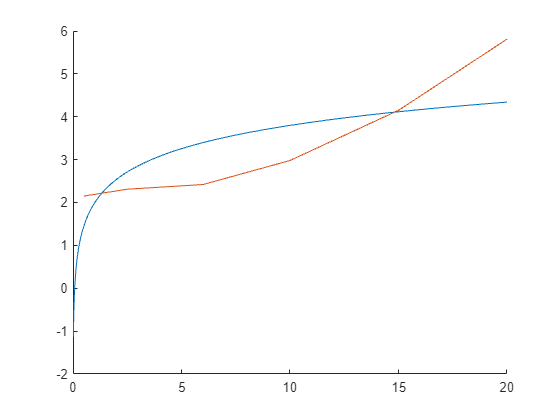

% Guardamos como funcion anonima, el resultado es espantoso
f2 = @(x) a*log(x) + b;
figure
hold on
fplot(f2, [0 20])
plot(xdata, ydata)
hold off

fprintf('y = %1f*log(x) + %1f', a, b)

y = 0.783199*log(x) + 1.995225

% ERROR SSE2
calcs = a*log(xdata) + b;     % Valores calculados con a y b obtenidas
sse2 = norm(abs(ydata - calcs),2)^2

sse2 = 4.4343

#### C) Comparación de las funciones de ajuste

- **(iii)** [1 punto] Representa gráficamente en 2D los puntos de los datos experimentales como asteriscos rojos, la función $f_1$ en negro y la función $f_2$ en azul. 

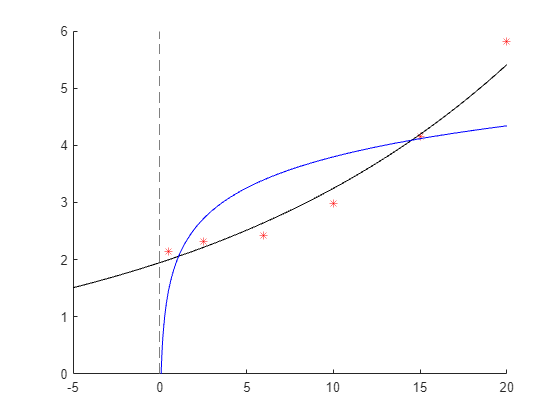

figure
hold on
plot(xdata,ydata,'*', 'color','r')
fplot(f1, 'color', 'black')
fplot(f2, 'color', 'blue')
hold off

`Documento preparado por I. Parada, 10 de abril de 2024`